# Analog line light control simulator

% This code simulates the accumulated light for a set amount of lines. The
% result of this code are two graphs.

% The first one visualises the light's intensity as a function of time as
% well as the time the sensor captures light in function of time.

% The second graph shows the accumulated light for every line.

% This simulator is used to create different graphs that are used in
% my thesis to explain the difference between analog and PWM control of the
% line light.


## Calculations

% The following parameters can be adjusted:
freq_LSC = 10000;   % [Hz]
duty_LSC = 80;      % 0-100%
offset_LSC = 0;     % 0-100% (will delay start of first period)
Brightness = 25;    % 0-100%
num_periods = 3;
time_res = 10000;   % higher --> more detailed graphs --> more computing time

% Calculate time vector
t = linspace(0, num_periods/freq_LSC, time_res);

% calculate offset index
offset_index = round((offset_LSC/100)*(time_res/num_periods));

% calculate PWM function for the LSC
fun_LSC = PWM(freq_LSC, offset_index, 1, duty_LSC, t);

% Calculate line light signal
fun_line_light = (Brightness/100)*ones(size(t));

% calculate average light for every period
exp_value = zeros(num_periods, 1);
for i = 1:num_periods
    cum_val = 0;
    for n = floor(i*(time_res/num_periods)-(time_res/num_periods)) + 1:floor(i*(time_res/num_periods))
        cum_val = cum_val + fun_LSC(n)*fun_line_light(n);
    end
    exp_value(i) = cum_val*100/(time_res/num_periods);
end


## Visualisations

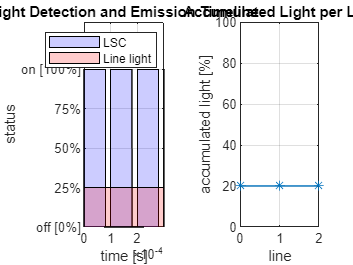

% Plot when LSC has sensor open and when Line light is emmiting light.
subplot(1,2,1)
plot(t, fun_LSC)
hold on
fill_handle_LSC = fill([t fliplr(t)], [fun_LSC zeros(size(fun_LSC))], 'b', 'FaceAlpha', 0.2);
plot(t, fun_line_light)
fill_handle_line_light = fill([t fliplr(t)], [fun_line_light zeros(size(fun_line_light))], 'r', 'FaceAlpha', 0.2);
hold off

title("Light Detection and Emission Timeline")
set(gca, 'ytick', [0 0.25 0.5 0.75 1])
set(gca, 'yticklabel', {'off [0%]', '25%', '50%', '75%','on [100%]'})
xlabel("time [s]")
ylabel("status")
ylim([0, 1.3])
legend([fill_handle_LSC fill_handle_line_light], {'LSC','Line light'},'Location', 'northeast')
grid on

% Plot collected light for every frame.
subplot(1,2,2)
plot(0:length(exp_value)-1, exp_value, '*-')

ylim([0, 100])
title("Accumulated Light per Line")
xlabel("line")
%xticks(0:ceil(num_periods/10):num_periods-1)
ylabel("accumulated light [%]")
grid on